# Step 2 - upsample the cropped ball 16× using bicubic interpolation


% Read the 35x35 cropped ball image
clc; close all;

I = imread('frame_0000_ball0.png');
disp(size(I));

   512   512     3



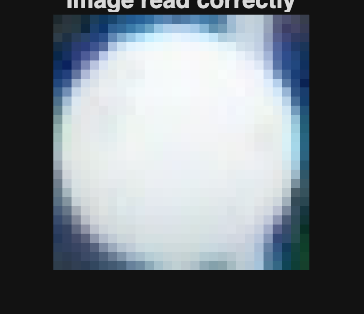

figure; imshow(I); title('Image read correctly');

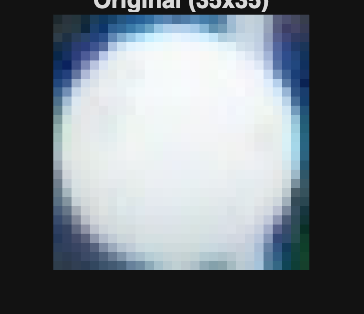



% Interpolate 16x using bilinear interpolation
I_nearest = imresize(I, 16, 'nearest');
I_bilinear = imresize(I, 16, 'bilinear');
I_bicubic = imresize(I,16,"bicubic");

%Choosing Bicubic for subsequent processing
I_up = I_bicubic;

% Display

figure; imshow(I); title('Original (35x35)');

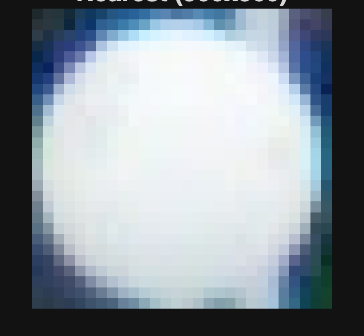

figure; imshow(I_nearest); title('Nearest (560x560)');

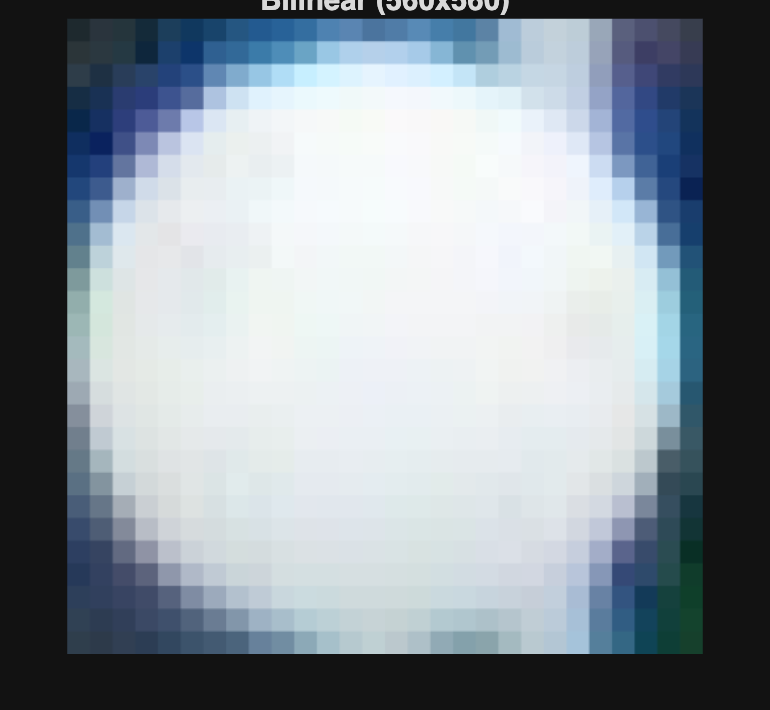

figure; imshow(I_bilinear); title('Bilinear (560x560)');

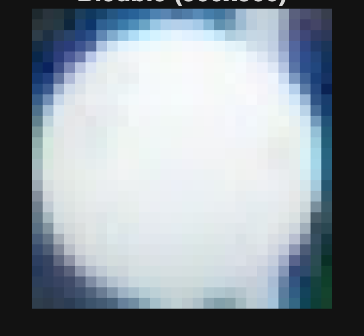

figure; imshow(I_bicubic); title('Bicubic (560x560)');

# Step 3 - Imparting a 16 pixel radius blur

## Gaussian Blur

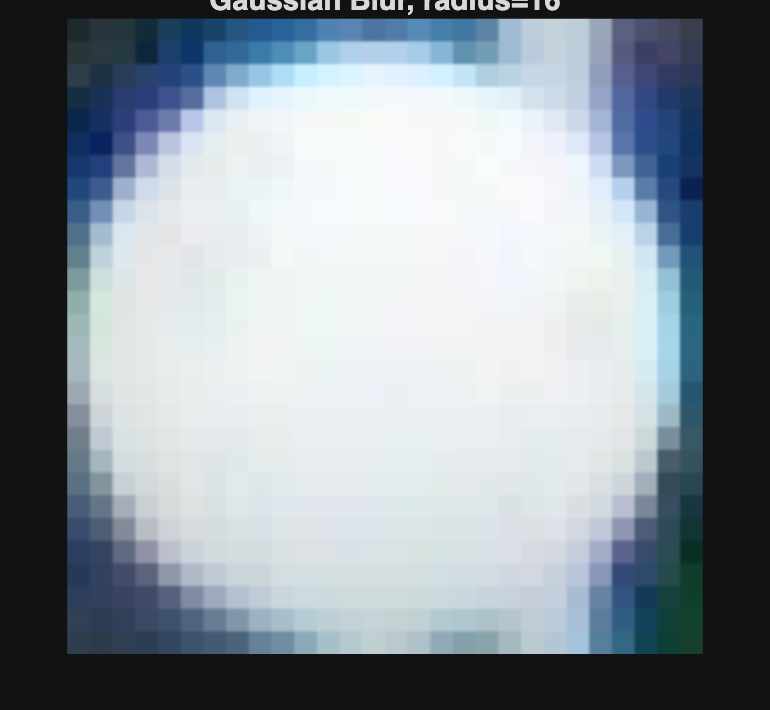

% Standard deviation roughly related to radius
sigma = 16;  
I_gauss = imgaussfilt(I_up, sigma);

figure; imshow(I_gauss); title('Gaussian Blur, radius=16');

## Triangle Blur

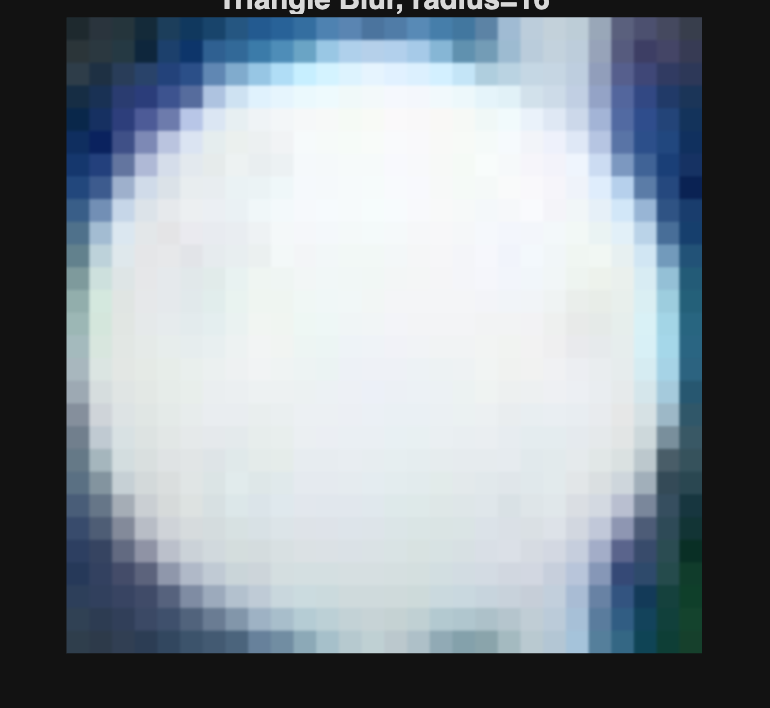

r = 16;

% First blur with box filter
h_box = fspecial('average', 2*r+1);
I_tmp = imfilter(I_up, h_box, 'replicate');

% Blur again with the same box filter
I_tri = imfilter(I_tmp, h_box, 'replicate');

imshow(I_tri); title('Triangle Blur, radius=16');

## Top-hat/box Blur

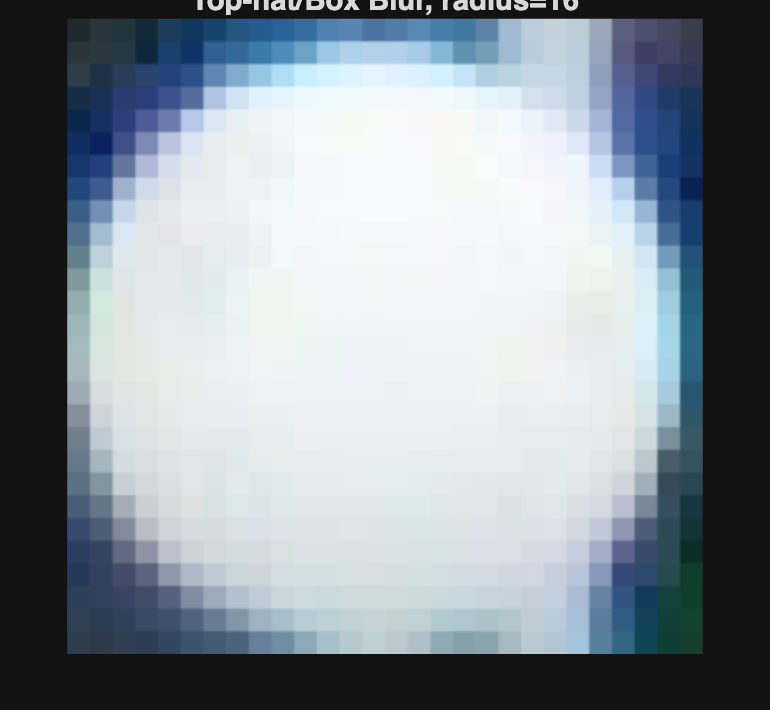

r = 16;
h = fspecial('average', 2*r+1);   % square box kernel, side=2r+1
I_box = imfilter(I_up, h, 'replicate');

figure; imshow(I_box); title('Top-hat/Box Blur, radius=16');

## Sinc Blur

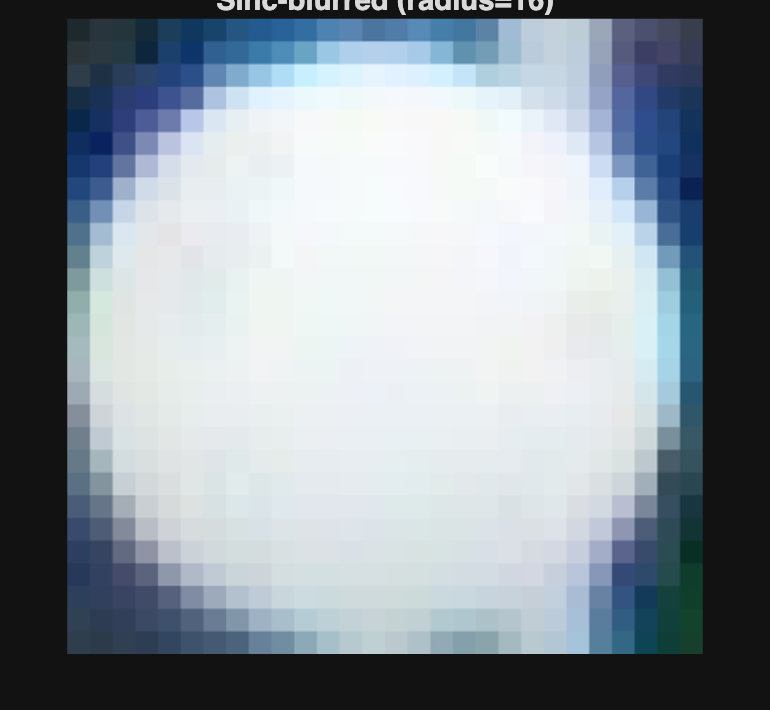

I_up_d = im2double(I_up);          % work in double

% Sinc blur parameters
r = 16;                % effective radius in pixels
sz = 4*r + 1;          % kernel size (odd)

% Create coordinate grid (centered)
[x, y] = meshgrid(-2*r:2*r, -2*r:2*r);
R = sqrt(x.^2 + y.^2);         % radial distance

% Build 2D sinc kernel explicitly: sin(pi * R/r) / (pi * R/r)
arg = pi * (R / r);
sinc_kernel = ones(size(R));   % initialize (R==0 --> 1)
nz = (R ~= 0);
sinc_kernel(nz) = sin(arg(nz)) ./ arg(nz);  % safe division

% Build 2D Hann window without using 'hann' function (works anywhere)
n = (0:sz-1)'; 
hann1 = 0.5 * (1 - cos(2*pi*n/(sz-1)));    % 1D Hann
window2d = hann1 * hann1';                 % outer product -> 2D

% Window the sinc and normalize
h_sinc = sinc_kernel .* window2d;
h_sinc = h_sinc / sum(h_sinc(:));

% Apply the filter (imfilter will apply to each color channel)
I_sinc = imfilter(I_up_d, h_sinc, 'replicate');

% Display
figure;

imshow(I_sinc);   title('Sinc-blurred (radius=16)');

# Step 4 - Edge Preserving filters for de-noising

% Bilateral filter (Spatial + Intensity Gaussian)
% You can tune 'DegreeOfSmoothing' and 'SpatialSigma'
I_bilat = imbilatfilt(I_gauss, 0.1, 16);   % example params

imshow(I_bilat); title('Edge-preserving Denoising (Bilateral)');

# Step 5 - Edge Detection

% Convert to grayscale if RGB
I_gray = rgb2gray(I_bilat);

% Edge detection (Canny)
edges_canny = edge(I_gray, 'Canny');

figure;
imshow(edges_canny);
title('Edges (Canny)');
se = strel('disk', 2);                  % structuring element
edges_closed = imclose(edges_canny, se);

imshow(edges_closed); title('Canny + Morphological Closing');
edges_filled = imfill(edges_closed, 'holes');

imshow(edges_filled); title('Edges after filling holes');
edges_clean = bwareafilt(edges_filled, 1);  % keep largest blob

imshow(edges_clean); title('Final Clean Ball Edge Mask');
I_overlay = imoverlay(I_up, edges_clean, [1 0 0]);  % red edges
imshow(I_overlay); title('Edges Overlayed on Original');

edges_canny_tuned = edge(I_gray, 'Canny', [0.4 0.8]); % adjust thresholds
imshow(edges_canny_tuned), title('Canny with tuned thresholds');
edges_sobel = edge(I_gray, 'Sobel');

figure;
imshow(edges_sobel);
title('Edges (Sobel)');
edges_prewitt = edge(I_gray, 'Prewitt');
edges_roberts = edge(I_gray, 'Roberts');
edges_log = edge(I_gray, 'log');  % Laplacian of Gaussian

figure;
subplot(1,3,1), imshow(edges_prewitt), title('Prewitt');
subplot(1,3,2), imshow(edges_roberts), title('Roberts');
subplot(1,3,3), imshow(edges_log), title('LoG');

I_gray = rgb2gray(I_bilat);
[Gx, Gy] = imgradientxy(I_gray, 'sobel');
[Gmag, ~] = imgradient(Gx, Gy);

% Normalize and threshold adaptively
Gmag = mat2gray(Gmag);
T = graythresh(Gmag);  % Otsu threshold
edges_grad = Gmag > 1.5*T;  % 1.5× for cleaner outer edge

figure;imshow(edges_grad); title('Gradient-magnitude edge mask');


% Detect edge points from Canny or gradient mask
[rows, cols] = find(edges_canny);

% Fit a circle (least squares)
[xc, yc, R, ~] = circfit(cols, rows); % requires small helper function

% Draw on image
imshow(I_gray); hold on;
viscircles([xc, yc], R, 'Color', 'r');
title('Detected Ball Boundary');



I_gray = rgb2gray(I_bilat);
[centers, radii, metric] = imfindcircles(I_gray, [160 480], ...
    'Sensitivity', 0.95, 'EdgeThreshold', 0.1);

imshow(I_gray);
viscircles(centers, radii, 'Color', 'r');
title('Hough Circle Detection');

function [xc,yc,R,a] = circfit(x,y)
    x = x(:); y = y(:);
    a = [x y ones(size(x))]\-(x.^2+y.^2);
    xc = -0.5*a(1);
    yc = -0.5*a(2);
    R = sqrt((a(1)^2+a(2)^2)/4 - a(3));
end
